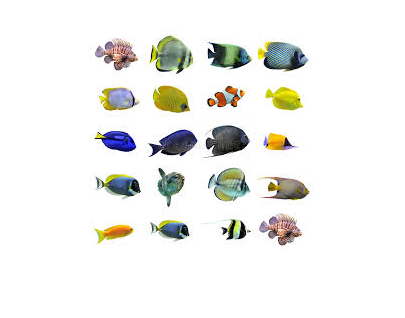

I = imread("Fish-9.jpg");
imshow(I)

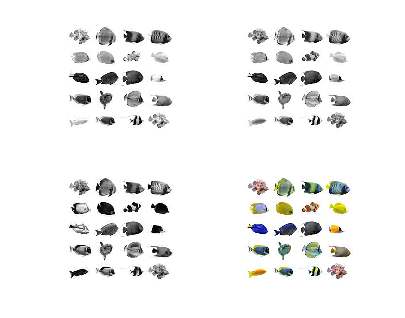

rmat = I(:,:,1);
gmat = I(:,:,2);
bmat = I(:,:,3);
subplot(2,2,1),imshow(rmat);
subplot(2,2,2),imshow(gmat);
subplot(2,2,3),imshow(bmat);
subplot(2,2,4),imshow(I);

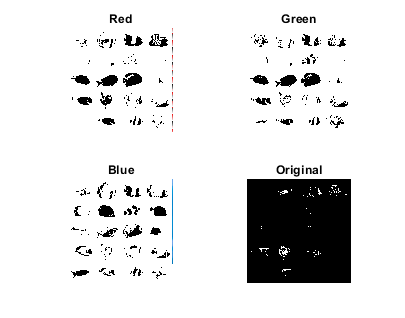

Grmat = im2bw(rmat,0.4);
Ggmat = im2bw(gmat,0.4);
Gbmat = im2bw(bmat,0.3);
IcompR = imcomplement(Grmat);
IBW = (IcompR&Ggmat&Gbmat);
subplot(2,2,1),imshow(Grmat);
title('Red');
subplot(2,2,2),imshow(Ggmat);
title('Green');
subplot(2,2,3),imshow(Gbmat);
title('Blue');
subplot(2,2,4),imshow(IBW);
title('Original');

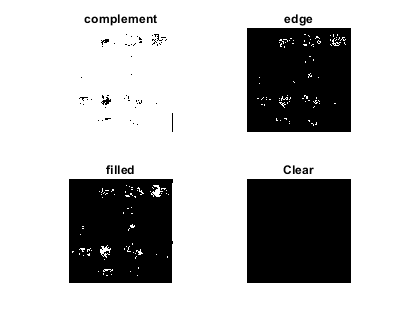

Icomp= imcomplement(IBW);
subplot (2,2,1),imshow (Icomp);
title ('complement');
BW1 = edge(Icomp,'sobel');
subplot(2,2,2),imshow(BW1);
title('edge');
I1 = imfill(BW1,'holes');
subplot(2,2,3),imshow(I1);
title('filled');
se = strel('disk',10);
Iopen = imopen(I1,se);
subplot(2,2,4), imshow(Iopen);
title('Clear');

%% Extract features
Iregion = regionprops(Iopen, 'centroid');
[labeled,numObjects] = bwlabel(Iopen,4);
stats = regionprops(labeled,'Eccentricity','Area','BoundingBox');
areas = [stats.Area];
eccentricities = [stats.Eccentricity];
%% Use feature analysis to count skittles objects
idxOfSkittles = find(eccentricities);
statsDefects = stats(idxOfSkittles);
figure, imshow(I);
hold on;
for idx = 1 : length(idxOfSkittles)
    h = rectangle('Position',statsDefects(idx).BoundingBox,'LineWidth',2);
    set(h,'EdgeColor',[.75 0 0]);
    hold on;
end
if idx >0
    title(['There are ', num2str(numObjects), ' fishes in the image!']);
end
hold off;